% LDR Gamma Calculation from Lux & Resistance Data
clear; clc; close all;

% ---- INPUT: Experimental Data ----
lux = [23545, 21219, 19382, 16347, 14095, 12284, 9771, 7972, 5277, 2779, 485, ...
       490.00, 2906.00, 5685.00, 7463.00, 9742.00, 12081.00, 14437.00, 17205.00, 18974.00, 21277.00, 23580.00, ...
       492.00, 3228.00, 5995.00, 7432.00, 9764.00, 12033.00, 14736.00, 17510.00, 18943.00, 21202.00, ...
       491.00, 2881.00, 4996.00, 7639.00, 10409.00, 11879.00, 14281.00, 16312.00, 18799.00, 20261.00, 22124.00];

resistance = [820.94, 883.01, 952.10, 1028.98, 1095.17, 1159.10, 1262.46, 1389.47, 1804.63, 2768.21, 10303.33, ...
              10809.25, 3058.41, 2046.42, 1582.52, 1289.30, 1075.98, 1015.14, 960.96, 908.56, 862.04, 820.94, ...
              11276.65, 3289.27, 2239.05, 1769.31, 1477.45, 1257.14, 1071.22, 934.54, 891.48, 857.88, ...
              9707.94, 2528.15, 1944.75, 1647.18, 1495.57, 1355.45, 1278.52, 1139.17, 1010.56, 891.48, 862.04];


% ---- Convert to Log Scale ----
log_lux = log(lux);
log_resistance = log(resistance);

% ---- Perform Linear Regression (logR = k*logL + logA) ----
coeffs = polyfit(log_lux, log_resistance, 1);
k = coeffs(1); % Slope of log-log plot
A = exp(coeffs(2)); % Intercept in normal scale
gamma = -k; % Gamma value

% ---- Display Results ----
fprintf('Computed Gamma (γ): %.4f\n', gamma);

Computed Gamma (γ): 0.6508


fprintf('Empirical Model: R = %.4f * L^(-%.4f)\n', A, gamma);

Empirical Model: R = 557523.3322 * L^(-0.6508)


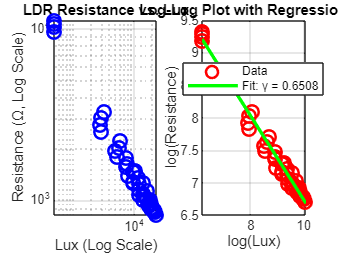


% ---- Plot Raw Data ----
figure;
subplot(1,2,1);
loglog(lux, resistance, 'bo', 'MarkerSize', 8, 'LineWidth', 1.5);
xlabel('Lux (Log Scale)');
ylabel('Resistance (Ω, Log Scale)');
title('LDR Resistance vs. Lux');
grid on;

% ---- Plot Log-Log with Fitted Line ----
subplot(1,2,2);
plot(log_lux, log_resistance, 'ro', 'MarkerSize', 8, 'LineWidth', 1.5);
hold on;
plot(log_lux, polyval(coeffs, log_lux), 'g-', 'LineWidth', 2);
xlabel('log(Lux)');
ylabel('log(Resistance)');
title('Log-Log Plot with Regression Fit');
legend('Data', sprintf('Fit: γ = %.4f', gamma), 'Location', 'Best');
grid on;